# Generate Experimental Data

KR: 

- Publication

- Modelisation Physique

- Reduction - Resultats

- Simulation temps reel - Speedgoat

video

- Phisical modeling

- Simulation manager

- Deep learning video

- Training

- Test

- Simulink Real-Time

Camtasia

## Open Model

modelName = 'simpleHelicopter_toReduce';
open_system(modelName)

train = true; % enable or disable network trainning

## Generate Simulation Scenarios

Set the simulation stop time in (s)

simStopTime = 300;

Create different simulation scenarios by specifying the the heat input stairs

initialScenarioVector = [[2e3:1e3:5e3] [5e3:-1e3:2.5e3]];
referenceHeatStates = {{initialScenarioVector,simStopTime},
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+150],simStopTime},                       
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+300],simStopTime},
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+450], simStopTime},
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+600],simStopTime}, 
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+650], simStopTime}};

Generate the simulation scenarios and save them in MAT files

for ix=1:numel(referenceHeatStates)
    generateInputs(scenarioDir, referenceHeatStates{ix}{1},...
    referenceHeatStates{ix}{2}, ix, 'heatIn')
end

## Generate Simulink Simulation Inputs

From the generated scenarios you can create "Simulink.SimulationInputs"

load_system(modelName)

clearvars simIn
fileList = listSimInpFiles(scenarioDir);
numCases = length(fileList);
scenario = {};
simIn(1:numCases) = Simulink.SimulationInput(modelName);

for ix=1:numCases
    fileName = split(fileList{ix},'.');
    scenario{ix} = load(fileList{ix});
    aux = split(fileName{1},'_');
    scenarioSimStopTime = aux{end};

    simIn(ix) = simIn(ix).setModelParameter('StopTime', scenarioSimStopTime);
    simIn(ix) = setVariable(simIn(ix), 'Qin', scenario{ix}.stateVecRef{1}.Values.Data', ...
        'Workspace', modelName);    
    simIn(ix) = setVariable(simIn(ix),'Qin_time', scenario{ix}.stateVecRef{1}.Values.Time', ...
        'Workspace', modelName);
end

## Simulate

Simulate in parallel and save the results

out = parsim(simIn);
save(fullfile(simOutDir,'simOuts'),'out') 

# Prepare Data for Training

To achieve better performance the data are resampled, normalized.

## Resample Data

Resample the date in seconds

sampleTime = 0.1; % s
commandSignals = [{'Altitude', 'Qin'}];
[resampledData, sigNames] = resampleSimulationData(out,sampleTime,commandSignals);

## Visualize Resampled data

*PH: See if we can remove wrapper functions*

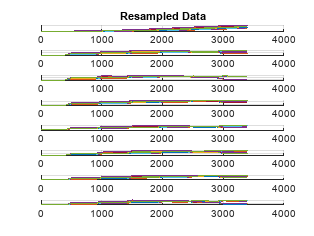

visualizeTrainData(resampledData,sigNames, 'Resampled Data')

## Prepare Data For Training

trainPercentage = 1; % the percentage of the data that they will be used for training
                       % the rest will be used for test
[dataTrain, dataTest, meanTrain, stdTrain] = prepareDataNormalization(resampledData, trainPercentage);
save meanTrain

save stdTrain

## Normalize Data

Apply gaussian normalization to the entire set of data.

*PH: zscore, cellfun*

normalize = @(x,mu,sigma) (x - mu) ./ sigma;
dataTrainNormComp = cellfun(@(x) normalize(x, meanTrain', stdTrain'), dataTrain, 'UniformOutput', false)

Error using cellfun
Non-scalar in Uniform output, at index 1, output 1.
Set 'UniformOutput' to false.

# Train a Neural Network

*PH: consider using trainnet*

## Define the Inputs/Outputs

Define the number of inputs and outputs of the neural network. Create respective datasets that correspond to the inputs and outputs of each timestep.

numFeatures = length(sigNames);
numResponses = length(sigNames)-length(commandSignals);
outStartIdx = length(commandSignals)+1;
numHiddenUnits = 150;
dropoutProbability = 0.2;

[XTrainSep, TTrainSep] = preprocessTrainData(dataTrainNorm, outStartIdx);

## Define Network Architecture

layers = [
    sequenceInputLayer(numFeatures,"Name","input")
    lstmLayer(numHiddenUnits,"Name","lstm","OutputMode","sequence")
    dropoutLayer(dropoutProbability,"Name","drop")
    fullyConnectedLayer(numHiddenUnits,"Name","fc_1")
    fullyConnectedLayer(numResponses,"Name","fc_2")
    % regressionLayer("Name","regressionoutput")
    ];


## Define Training Options

opts = trainingOptions("adam",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",1e-2,...
    "MaxEpochs",500,...
    "Shuffle","every-epoch",... 
    "LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",200,...
    "LearnRateDropFactor",0.1,...
    "ValidationFrequency",10,...
    "Plots","training-progress");

## Train the Network

*PH: Envoyer des donnes*

if train
    [net, traininfo] = trainNetwork(XTrainSep,TTrainSep,layers,opts);
    net = resetState(net);
end

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss
    _________    _____    ___________    _________    ____________
            1        1       00:00:01         0.01          1.1257
           50       50       00:00:43         0.01       0.0059069
          100      100       00:01:24         0.01       0.0037703
          150      150       00:02:06         0.01       0.0032833
          200      200       00:02:52         0.01       0.0031728
          250      250       00:03:34        0.001       0.0030617
          300      300       00:04:16        0.001       0.0029753
          350      350       00:04:57        0.001       0.0029836
          400      400       00:05:38        0.001        0.002976
          450      450       00:06:19       0.0001        0.002895
          500      500       00:07:00       0.0001       0.0029317
Training stopped: Max epochs completed


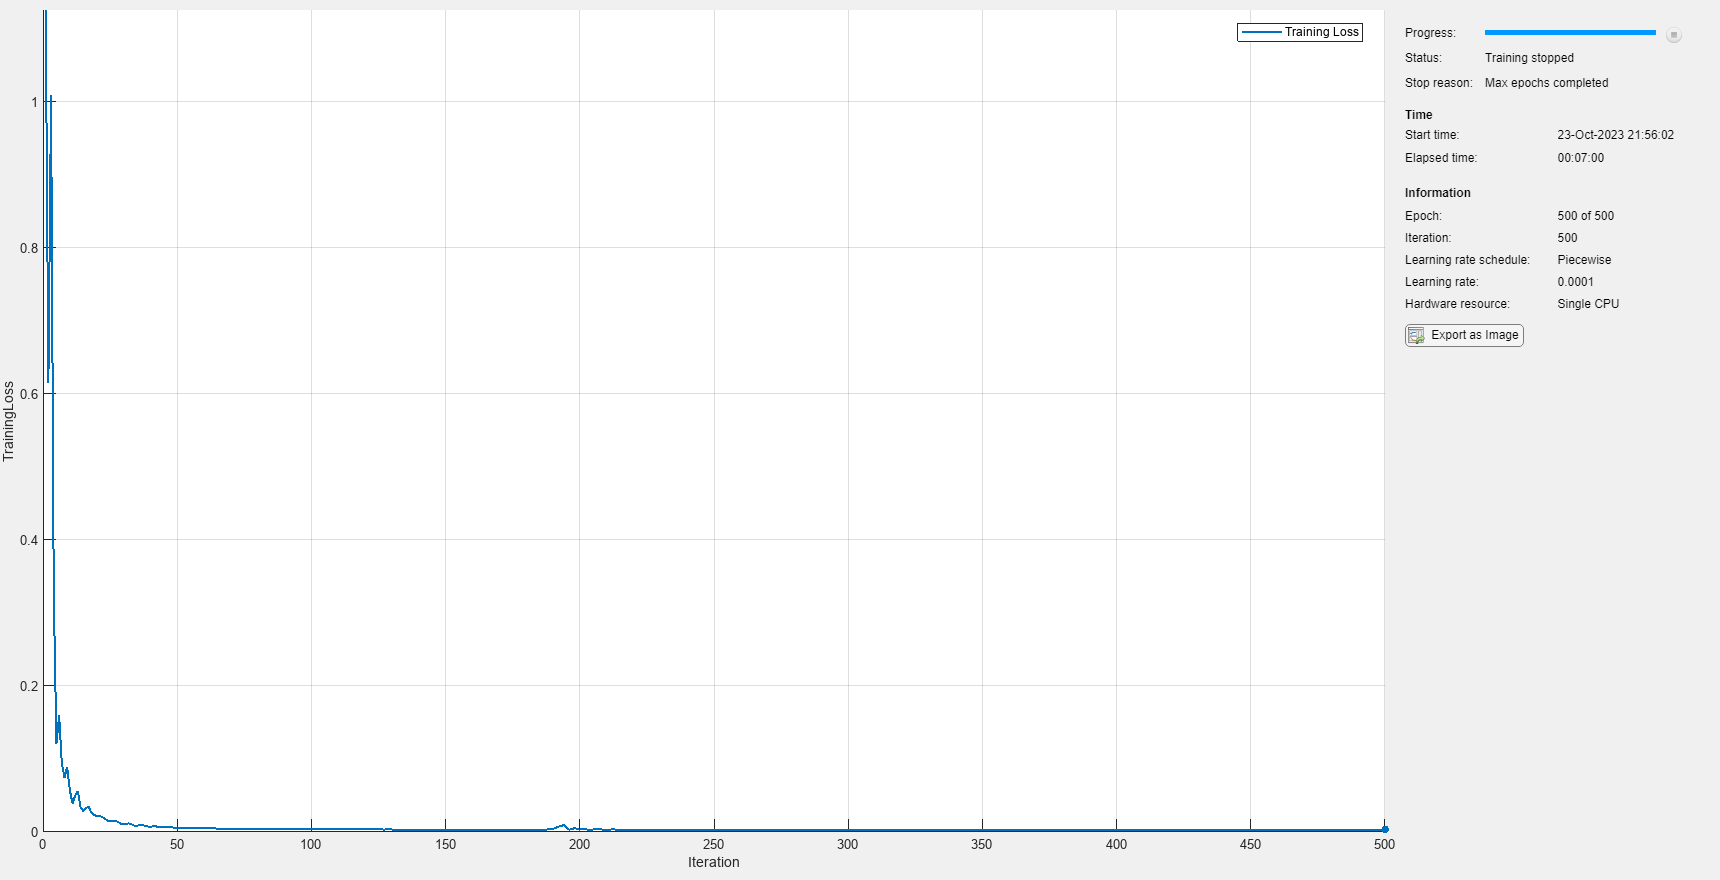

nnet =   dlnetwork with properties:

         Layers: [5×1 nnet.cnn.layer.Layer]
    Connections: [4×2 table]
     Learnables: [7×3 table]
          State: [2×3 table]
     InputNames: {'input'}
    OutputNames: {'fc_2'}
    Initialized: 1

  View summary with summary.


for ix=1:numel(XTrainSep)

XTrainSepReversed{ix} = XTrainSep{ix}';
TTrainSepReversed{ix} = TTrainSep{ix}';

end

nnet = trainnet(XTrainSepReversed,TTrainSepReversed,layers,'mean-squared-error',opts)

## Integrate Trained LSTM Network in Simulink

You can use recurrent neural networks in simulink by using the "Stateful Predict" block 

reducedModel = 'simpleHelicopter_ROM';
open_system(reducedModel)

# Evaluate results

Compare original and reduced model rregarding their resutls and simulation performance. This comparison is in a scenario that has not been included in the trainning.

mode = 'Custom';

## Simulate the ROM

set_param([reducedModel,'/HeatIn'],'LabelModeActivechoice', mode)
romSim = sim(reducedModel);
romRunID = Simulink.sdi.Run.getLatest;

## Simulate the Physical Model

referenceModel = 'simpleHelicopter_reference';
open_system(referenceModel)
set_param([referenceModel,'/HeatIn'],'LabelModeActivechoice', mode)
refSim = sim(referenceModel);
refRunID = Simulink.sdi.Run.getLatest;

## Compare with Simulink Test

import matlab.unittest.TestCase
import Simulink.sdi.constraints.MatchesSignal
import Simulink.sdi.constraints.MatchesSignalOptions

Create a test case:

testCase = TestCase.forInteractiveUse;    

Set the accepted relative and absolute tolerance:

relTol = 1e-2;
absTol = 6;

Compare different signals between ROM LSTM model and original model.

for ix=1:length(sigNames)
    basselineSig = refSim.logsout.getElement(sigNames{ix});
    romSig = romSim.logsout.getElement(sigNames{ix});
    testCase.verifyThat(romSig,MatchesSignal(basselineSig,'RelTol',relTol))
end

Unrecognized function or variable 'sigNames'.

## Visualize in Simulation Data Inspector

Simulink.sdi.compareRuns(refRunID.id,romRunID.id,'RelTol',relTol,'AbsTol',absTol)

ans =   DiffRunResult with properties:

       MatlabVersion: '23.2.0.2365128 (R2023b)'
              RunID1: 2548
              RunID2: 2487
     BaselineRunName: 'Run 4: simpleHelicopter_reference'
    CompareToRunName: 'Run 3: simpleHelicopter_ROM'
               Count: 8
         DateCreated: 24-Oct-2023 13:01:14
     GlobalTolerance: [1×1 struct]
             Summary: [1×1 struct]
             Options: {'Units'  'MustMatch'}
              Status: Completed
          StopReason: []


Simulink.sdi.view

## Performance comparison

*KR: focus in the results*

Compare the Simulation Metadata containing information regarding the initialization, execution and total time of the simulation.

The timing info for the reference simulation

refSim.SimulationMetadata.TimingInfo

ans = struct with fields:
          WallClockTimestampStart: '2023-10-24 11:07:33'
           WallClockTimestampStop: '2023-10-24 11:08:04'
    InitializationElapsedWallTime: 7.2704
         ExecutionElapsedWallTime: 24.1214
       TerminationElapsedWallTime: 0.0305
             TotalElapsedWallTime: 31.4223
                     ProfilerData: 'Profiler is not enabled'


The timing info for the ROM model

romSim.SimulationMetadata.TimingInfo

ans = struct with fields:
          WallClockTimestampStart: '2023-10-24 11:07:10'
           WallClockTimestampStop: '2023-10-24 11:07:30'
    InitializationElapsedWallTime: 3.1608
         ExecutionElapsedWallTime: 17.5501
       TerminationElapsedWallTime: 0.0430
             TotalElapsedWallTime: 20.7539
                     ProfilerData: 'Profiler is not enabled'


Compare performance:

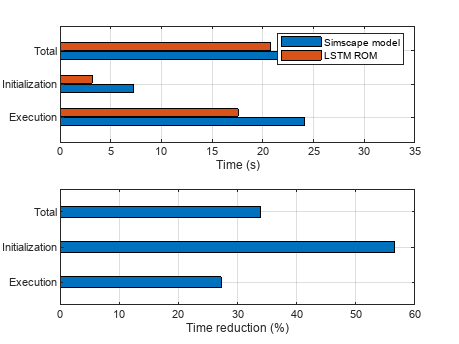

compareSimulationPerformance(refSim, romSim)

# Real-Time Simulation

KR: Speedgoat

Use Simulink Desktop Real-Time to simulate the model in real time:

open_system('simpleHelicopter_ROM_realTime')

 Let's take-off !